Problem 2.6 (* Projektowanie sygnału alarmowego). Ustaw fpr=8000; Nx=5*fpr; i wygeneruj sygnał x trwający 5 sekund. Skorzystaj z tabeli 2.2 i zaprojektuj sygnał z łączną modulacją AM-FM dla wozu strażackiego, karetki pogotowia oraz samochodu policji. Przeanalizuj kształt, posłuchaj. (sound(x,fpr);)

interesująca nas część tabeli 2.2

fpr = 8000;
Nx = 10*fpr;
dt = 1/fpr;
n = 0:Nx-1;
t = dt*n;
A = 1;

Samochód policji, pierwsza próba (zgadywanie):

fa = 10;    % czestotliwosc sygnalu modulujacego AM
            % czyli amplituda bedzie zmieniana z ta czestotliwoscia
kA = 0.7;   % glebokosc modulacji
mA = sin(2*pi*fa*t);

fc = 600;   % czestotliwosc nosna
fm = 2;     % czestotliwosc sygnalu modulujacego FM
            % (czyli częstotliwość nośna będzie zmieniania z tą częstotliwością - np. 2Hz = 2 razy na sekundę)
kF = 10;    % głębokość modulacji częstotliwości: mówi jak bardzo zmieni się częstotliwość chwilowa
mF = sin(2*pi*fm*t);

x = A*(1+kA*mA) .* sin(2*pi*(fc*t+kF*cumsum(mF)*dt));

audiowrite('policja zgadywanie.wav',x,fpr,BitsPerSample=32);
% soundsc(x,fpr);

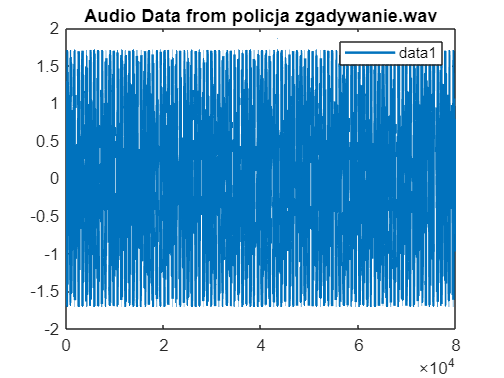

% Import audio
[data, fs] = audioread("C:\Users\ttome\Desktop\CPS\cyfrowe-przetwarzanie-sygnalow\egzamin\policja zgadywanie.wav");

% Display results
plot(data, "LineWidth", 1.5);
title("Audio Data from policja zgadywanie.wav", "Interpreter", "none");
legend;

Wydaje mi się, że częstotliwość chwilowa, która "odpowiada za słyszany dźwięk" zbyt szybko się zmienia, więc spróbuję zmniejszyć fm (częstotliwość sygnału modulującego), czyli częstotliwość chwilowa będzie się wolniej zmieniać. Zwiększę też głębokość modulacji, żeby częstotliwość chwilowa bardziej się zmieniała

fa = 2;     % czestotliwosc sygnalu modulujacego AM
            % czyli amplituda bedzie zmieniana z ta czestotliwoscia
kA = 0.3;   % glebokosc modulacji
mA = sin(2*pi*fa*t);

fc = 700;   % czestotliwosc nosna
fm = 0.2;     % czestotliwosc sygnalu modulujacego FM
            % (czyli częstotliwość nośna będzie zmieniania z tą częstotliwością - np. 2Hz = 2 razy na sekundę)
kF = 200;    % głębokość modulacji częstotliwości: mówi jak bardzo zmieni się częstotliwość chwilowa

mF = sin(2*pi*fm*t);

x = A*(1+kA*mA) .* sin(2*pi*(fc*t+kF*cumsum(mF)*dt));
audiowrite('policja.wav',x,fpr,BitsPerSample=32);
% soundsc(x,fpr);

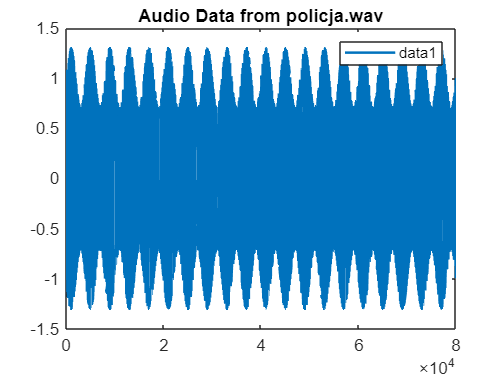

% Import audio
[data2, fs2] = audioread("C:\Users\ttome\Desktop\CPS\cyfrowe-przetwarzanie-sygnalow\egzamin\policja.wav");

% Display results
plot(data2, "LineWidth", 1.5);
title("Audio Data from policja.wav");
legend;

Myślę, że jest dosyć podobne do rzeczywistej syreny: [https://www.youtube.com/watch?v=9dj2NlLr_jI](https://www.youtube.com/watch?v=9dj2NlLr_jI)

Na podobnej zasadzie spróbuję wygenerować sygnały podobne dla karetki pogotowia i wozu strażackiego

Wóz strażacki: [https://www.youtube.com/shorts/3CthyDeQx64](https://www.youtube.com/shorts/3CthyDeQx64)

fa = 2;     % czestotliwosc sygnalu modulujacego AM
            % czyli amplituda bedzie zmieniana z ta czestotliwoscia
kA = 0.1;   % glebokosc modulacji
mA = sin(2*pi*fa*t);

fc = 600;   % czestotliwosc nosna
fm = 3;     % czestotliwosc sygnalu modulujacego FM
            % (czyli częstotliwość nośna będzie zmieniania z tą częstotliwością - np. 2Hz = 2 razy na sekundę)
kF = 350;    % głębokość modulacji częstotliwości: mówi jak bardzo zmieni się częstotliwość chwilowa

mF = sin(2*pi*fm*t);

x = A*(1+kA*mA) .* sin(2*pi*(fc*t+kF*cumsum(mF)*dt));
audiowrite('straz.wav',x,fpr,BitsPerSample=32);
% soundsc(x,fpr);

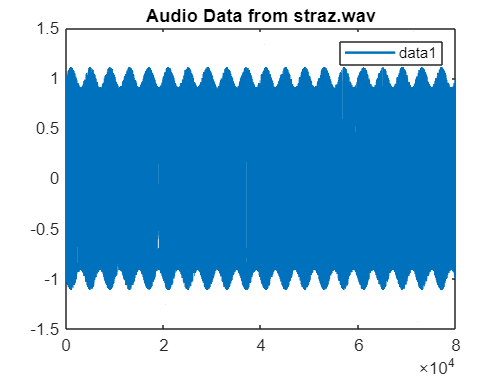

% Import audio
[data3, fs3] = audioread("C:\Users\ttome\Desktop\CPS\cyfrowe-przetwarzanie-sygnalow\egzamin\straz.wav");

% Display results
plot(data3, "LineWidth", 1.5);
title("Audio Data from straz.wav");
legend;

fa = 0.5;     % czestotliwosc sygnalu modulujacego AM
            % czyli amplituda bedzie zmieniana z ta czestotliwoscia
kA = 0.1;   % glebokosc modulacji
mA = sin(2*pi*fa*t);

fc = 800;   % czestotliwosc nosna
fm = 0.15;     % czestotliwosc sygnalu modulujacego FM
            % (czyli częstotliwość nośna będzie zmieniania z tą częstotliwością - np. 2Hz = 2 razy na sekundę)
kF = 400;    % głębokość modulacji częstotliwości: mówi jak bardzo zmieni się częstotliwość chwilowa

mF = sin(2*pi*fm*t);

x = A*(1+kA*mA) .* sin(2*pi*(fc*t+kF*cumsum(mF)*dt));
audiowrite('karetka.wav',x,fpr,BitsPerSample=32);
% soundsc(x,fpr);

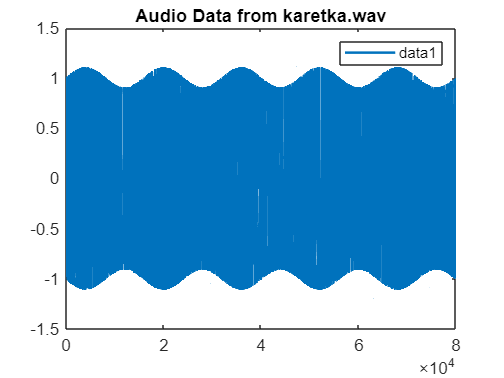

% Import audio
[data4, fs4] = audioread("C:\Users\ttome\Desktop\CPS\cyfrowe-przetwarzanie-sygnalow\egzamin\karetka.wav");

% Display results
plot(data4, "LineWidth", 1.5);
title("Audio Data from karetka.wav");
legend;